# Init 

close all;
clear;

add necessary folder to the path

cd ..
init

# Load data

enter in the folder

cd test_03_08_2017_1_outdoor

init autoranging struct

autoranging = struct();

load data from **anchor** autoranging procedure

autoranging = load_data_anch_autoranging('a2a_anch_', autoranging);

Loading data of anchor 0.


Loading data of anchor 1.


Loading data of anchor 2.


load data from **tag** autoranging procedure

autoranging = load_data_tag_autoranging('a2a_tag_',autoranging);

Loading data of tag over anchor 0.


Loading data of tag over anchor 1.


Loading data of tag over anchor 2.


load data from **laser** measurament

[autoranging, plane_height] = laser_data(autoranging);

load data from standard trilateration (ranges) experiment

path_ranges = load_data_path_ranges('path.csv');

Loading path data.


# Postprocessing

Evaluate the anchor position from ranges

anchor_position = eval_anch_pos(autoranging)

anchor_position = struct with fields:
    joined: [3×4 double]
       tag: [3×4 double]
     laser: [3×4 double]


Evaluate the tag coordinates using ranges data

trilateration = trilateration_all_types(path_ranges, anchor_position)

trilateration = struct with fields:
    joined: [1×1 struct]
       tag: [1×1 struct]
     laser: [1×1 struct]


# Autoranging ranges 

The autoranging ranges are shown

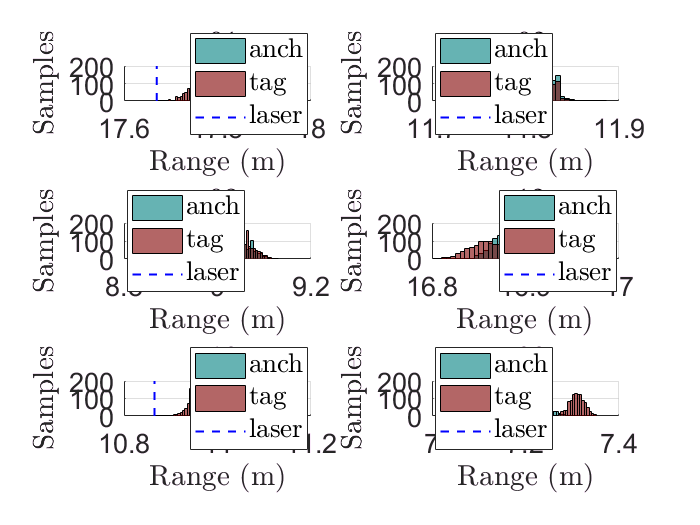

plot_a2a_histograms(autoranging);

# 3D path

Select the autoranging ranges acquisition mode

The following can be chosen

- joined

- laser

- tag

anchor_pos_data_type = 'joined';

 draw the ground and the anchors 

draw_world(anchor_position.(anchor_pos_data_type), plane_height, 'Trilateration comparison using autoranging');

 plot path for different algorithms

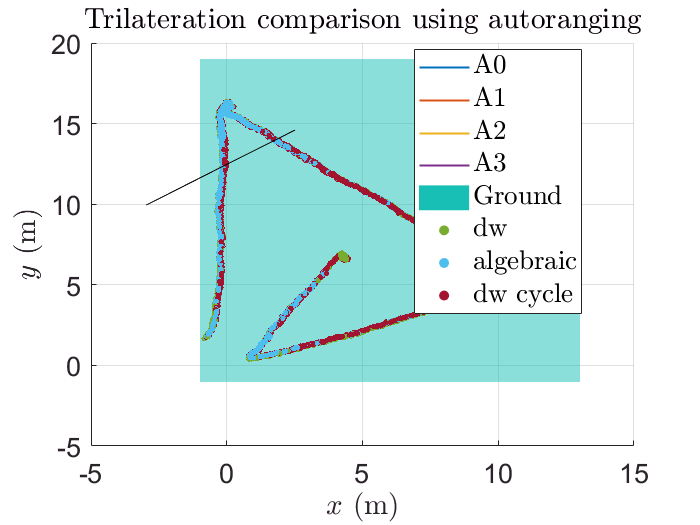

for algorithm = fields(trilateration.(anchor_pos_data_type))'
    plot_path(trilateration.(anchor_pos_data_type).(algorithm{:}).x,...
              trilateration.(anchor_pos_data_type).(algorithm{:}).y,...
              trilateration.(anchor_pos_data_type).(algorithm{:}).z,...
              plane_height, 4000, algorithm{:});
end

# Plot cartesian components

set the anchor_position data type. 

The following can be chosen

- joined

- laser

- tag

anchor_pos_data_type = 'joined';

## plot x component

component = 'x';
figure;

cycle over algorithms

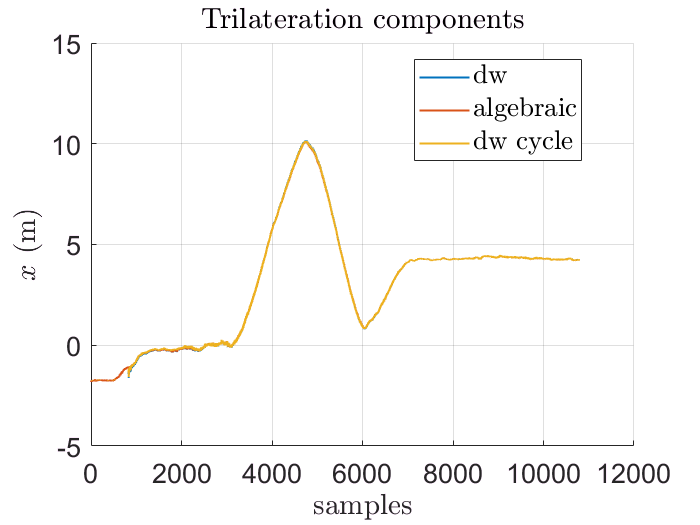

for alg_name = fieldnames(trilateration.(anchor_pos_data_type))'

  get the component

    signal = trilateration.(anchor_pos_data_type).(alg_name{:}).(component);

  plot the component

    plot_component(signal, 3000, "Trilateration components", component, alg_name{:})     
end

## plot y component

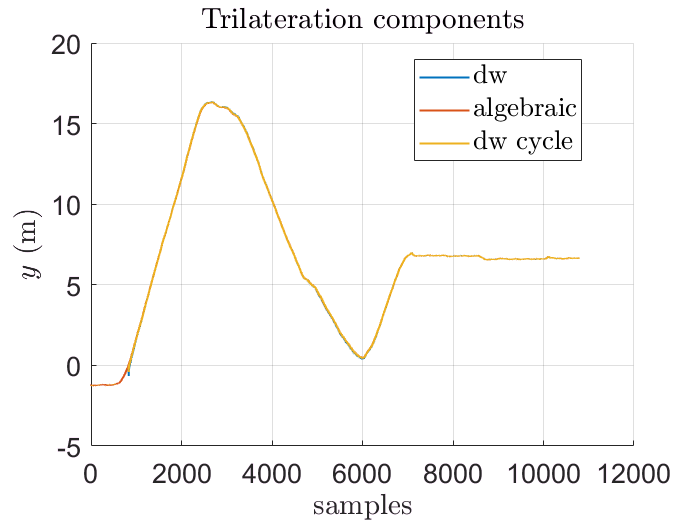

component = 'y';
figure;

cycle over algorithms

for alg_name = fieldnames(trilateration.(anchor_pos_data_type))'

  get the component

    signal = trilateration.(anchor_pos_data_type).(alg_name{:}).(component);

  plot the component

    plot_component(signal, 3000, "Trilateration components", component, alg_name{:})     
end

## plot z component

component = 'z';
figure;

cycle over algorithms

for alg_name = fieldnames(trilateration.(anchor_pos_data_type))'

  get the component

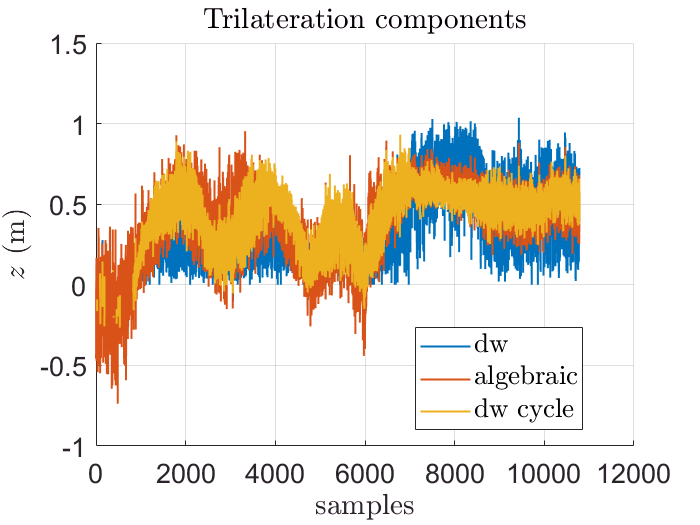

    signal = trilateration.(anchor_pos_data_type).(alg_name{:}).(component);

  plot the component

    plot_component(signal, 3000, "Trilateration components", component, alg_name{:})     
end